% a clear MATLAB workspace is a clear mental workspace
close all; clear

## create data for the plot

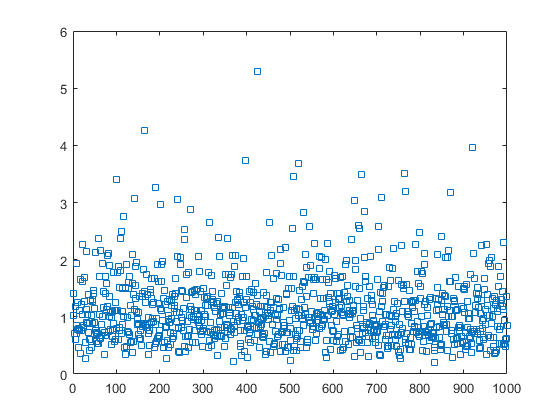

% number of data points
n = 1000;

% generate log-normal distribution
data = exp( randn(n,1)/2 );
plot(data, 's')

## show a histogram

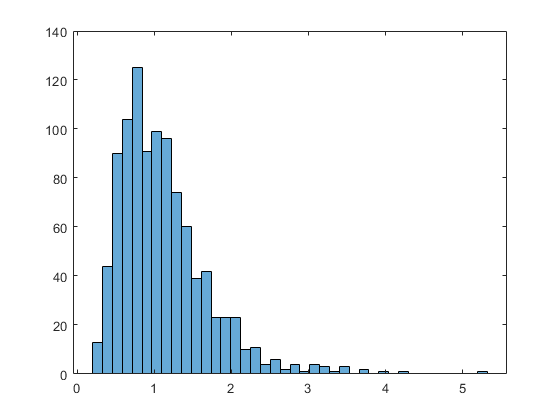

% number of histogram bins
k = 40;

figure(1), clf

% one way to show a histogram
histogram(data,k)

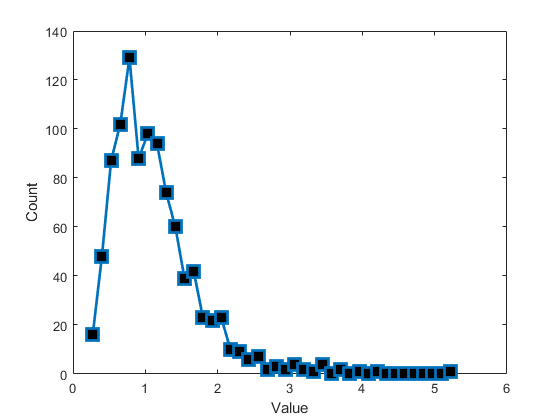


% another option
[y,x] = hist(data,k);
plot(x,y,'s-','linew',2,'markersize',12,'markerfacecolor','k')
xlabel('Value')
ylabel('Count')

## movie showing histograms with increasing bins

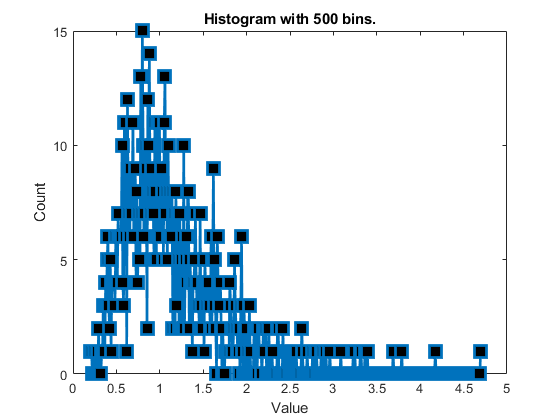

bins2try = round( linspace(5,n/2,30) );

h = plot(x,y,'s-','linew',2,'markersize',12,'markerfacecolor','k');
xlabel('Value'), ylabel('Count')

for bini=1:length(bins2try)
    % use hist to get histogram graph data for this bin count
    [y,x] = hist(data,bins2try(bini));
    
    % update xdata and ydata
    set(h,'XData',x,'ydata',y);
    
    % update title
    title([ 'Histogram with ' num2str(bins2try(bini)) ' bins.' ])
    pause(.1)
end

## done.

Exercise

bins2try = round( linspace(5,n/2,30) );

h = plot(x,y,'s-','linew',2,'markersize',12,'markerfacecolor','k');
xlabel('Value'), ylabel('Count')
sum = 0

sum = 0

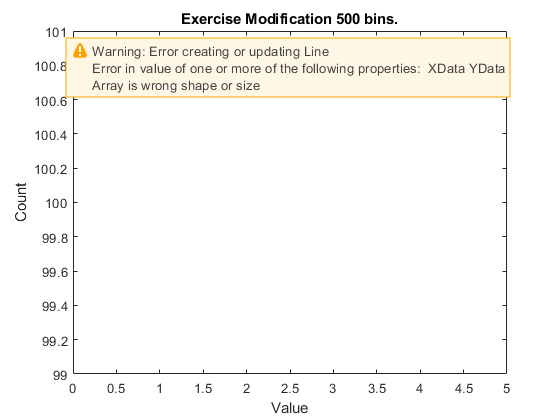

sum =    584   351    51    12     2


converted = 100.0000

sum =     33   110   179   186   152   107    85    47    41    20    10    10     4     5     3     4     0     2     0     1     0     1


converted = 100.0000

sum =      6    33    59    87    91   122   101   103    66    66    51    41    50    17    27    20    12    10     5     6     4     4     3     5     1     0     3     3     0     0     1     1     0     0     1     0     0     0     1


converted = 100.0000

sum =      4     9    31    40    56    65    64    78    78    71    74    58    43    47    37    35    29    39    23    10    22    16    11     6    11     5     5     3     4     3     3     2     2     4     1     1     0     2     2     2     0     0     0     1     1     0     0     0     0     1


converted = 100.0000

sum =      3     3    13    26    29    46    46    54    45    58    57    58    55    60    51    36    32    35    34    28    23    25    30    24    12     6    18    11    15     7     5     8     7     3     2     3     3     4     2     3     1     1     2     4     1     0     1     0     0     2


converted = 100.0000

sum =      2     4     4    19    18    23    31    37    41    43    37    48    46    52    43    45    42    49    34    29    26    28    30    21    23    18    20    21    24    18     7     6    12    14    13     7     5     4     6     7     3     3     0     4     3     3     2     2     3     1


converted = 100.0000

sum =      2     2     2     9    18    15    20    24    30    31    33    41    31    33    43    41    42    37    38    36    42    34    25    25    19    23    30    16    20    19    14    17    16    23    17    13     3     5    11    12     6    11     7     4     3     5     5     5     4     1


converted = 100.0000

sum =      2     1     3     3    10    18    11    18    21    25    26    31    28    34    26    26    40    30    42    31    31    34    33    35    30    28    19    23    16    20    23    19    14    19    15    11    13    16    16    17    16     7     4     4    10    10     6     8     9     4


converted = 100.0000

sum =      2     1     2     1     6    11    15    10    13    17    22    23    27    25    24    31    25    18    37    27    28    36    29    27    25    30    31    30    25    20    18    22    13    19    17    20    14    14    16    13     9    12    13    14    18     8    17     6     3     3


converted = 100.0000

sum =      2     1     1     2     2     7    12    11    11    12    15    17    23    20    21    24    23    28    23    16    25    32    25    30    28    23    25    23    28    24    33    21    20    19    17    15    13    16    17    20    12     9    16    11    12     9    11    12    10    14


converted = 100.0000

sum =      2     0     2     2     0     5     8    14     6    10    11    13    17    17    17    19    26    16    24    23    22    15    22    31    23    19    31    23    22    21    21    26    21    29    22    20    18    16    12    14    12    15    14    17    14    10    11    14    10    10


converted = 100.0000

sum =      2     0     1     2     1     2     6     5    14    10     6    11    12    15    13    20    16    17    21    18    23    19    19    13    21    28    19    19    25    26    21    21    18    18    25    20    26    19    18    18    13    15    14    11    12    11    15    16    12    14


converted = 100.0000

sum =      2     0     1     1     2     0     4     6     8    11     8     7     9    11    14    13    16    12    17    21    16    17    24    14    19    13    12    29    21    19    15    30    18    19    19    20    14    21    21    22    21    17    17    15    12    12    13    10    10    10


converted = 100.0000

sum =      2     0     1     1     2     0     2     4     7     8    10     6     8     7    11     9    14    14    16    14    17    17    14    17    20    14    17    13    10    23    24    15    17    21    23    19    16    18    18    13    21    19    16    23    15    15    17    10    16    10


converted = 100.0000

sum =      2     0     1     0     2     1     0     4     4     5    12     7     6     7     6    12     7    13    13    16     7    17    15    17    11    18    18    14    17     9    13    17    25    13    21    12    27    17    16    13    19    16    12    21    17    12    24    15    15    16


converted = 100.0000

sum =      2     0     0     1     1     2     0     2     3     6     5    11     5     6     7     6    10     9    12    10    14    11    13    17    13    12    13    16    15    13    15    10    12    18    23    13    14    14    19    22    14    16    15    15    17    10    17    18    12    23


converted = 100.0000

sum =      2     0     0     1     1     2     0     0     3     5     5     6     8     6     5     7     6     9     7    11    10    12    14     7    15    11    18    10    14    14    15    14    12    10    11    16    19    17    11    18    10    25    13    15    14    15    13    16     9    17


converted = 100.0000

sum =      1     1     0     1     1     1     1     0     2     3     3     5     8     8     4     6     6     6     9     7    11     7    11    13     9    12    14    10    13    12    13    15    12    13    12     9    11    12    17    18    12    17     8    18    20    14    15    11    14    12


converted = 100.0000

sum =      1     1     0     1     0     1     2     0     0     2     4     6     3    10     5     3     6     6     6     6     9     6    11     9    12    10     9    12    12    13    12     7    16    14    12    12    11     9    10     7    17    21    12    11    16     9    18    18    11    14


converted = 100.0000

sum =      1     1     0     1     0     1     2     0     0     2     2     4     5     5     9     4     5     3     7     5     6     7     6    12     8    10    12     6    12    10    10    15     8    12    11    16    11    11     9     9     9     8    16    19    13    10    14     7    18    19


converted = 100.0000

sum =      1     1     0     1     0     1     1     1     0     0     2     3     4     4     6     8     5     5     2     7     5     6     6     7     9     8     9    11     9     8    10    13    10    10    11    10    10    16    10    11     7    10     8     8    15    15    15     9    12    13


converted = 100.0000

sum =      1     1     0     0     1     0     1     2     0     0     2     2     3     6     0     8     6     5     5     2     7     5     4     8     6     9     7     8     9    12     5    11     7    10    15    10     7    11    12    13    10    11     6    10     8     7    14    12    16    10


converted = 100.0000

sum =      1     1     0     0     1     0     1     1     1     0     0     2     3     3     5     3     7     6     3     5     2     6     6     4     8     4     8     8     7     9    10     7     7    11    12     5    14     7     7    12    11    13     9     9     9     8     9     6     8    13


converted = 100.0000

sum =      1     1     0     0     1     0     1     0     2     0     0     2     1     2     4     4     5     8     3     3     5     3     6     4     5     6     6     5    10     5     9     9     9     5    11     6    11    11     9     8    10     7    11    12    11     8     8     8     8     7


converted = 100

sum =      1     1     0     0     1     0     0     1     2     0     0     0     2     2     4     5     0     6     8     3     3     4     4     5     4     5     6     6     3    10     6     7     8    11     5     7     9    11     4    14     8     8     8     9    12     8    11     9     6     9


converted = 100.0000

sum =      1     1     0     0     1     0     0     1     1     1     0     0     2     1     2     3     5     2     5     7     4     2     5     3     5     4     4     6     5     5     8     6     7     8     9     6     5    11     6    11     7    11     7     7     9     9    12     7    10    11


converted = 100.0000

sum =      1     1     0     0     0     1     0     1     0     2     0     0     0     2     2     3     2     4     5     5     4     4     2     5     3     5     4     4     6     4     6     8     5     6     7     8    10     3     8     8     9     5    13     7     6     6    11     8    11     8


converted = 100.0000

sum =      1     1     0     0     0     1     0     1     0     2     0     0     0     2     1     2     3     5     0     5     7     4     3     4     2     3     5     4     4     4     5     5     7     7     4     8     6    10     6     3    11     6    11     4    12     7     5     9     8    10


converted = 100.0000

sum =      1     1     0     0     0     1     0     0     1     1     1     0     0     0     2     2     2     2     5     0     6     8     2     3     4     2     3     5     4     4     4     5     4     5     9     4     7     7     7     8     4     7     8     7     7    10     8     7     7     6


converted = 100.0000

sum =      1     1     0     0     0     1     0     0     1     0     2     0     0     0     1     1     3     3     1     4     3     5     6     3     2     5     1     4     4     4     4     3     6     4     4     7     6     6     6     6    10     4     3    11     6    11     1    12     7     6


converted = 100.0000

for bini=1:length(bins2try)
    % use hist to get histogram graph data for this bin count
    [y,x] = hist(data,bins2try(bini));
    sum = y
    converted = 100*y/sum
    
    % update xdata and ydata
    set(h,'XData',x,'ydata',converted);
    
    % update title
    title([ 'Exercise Modification ' num2str(bins2try(bini)) ' bins.' ])
    pause(.1)
end